`Task 2: Overview`

This livescript is meant to give an overview of the functions and results that are already implemented. First we have sample possibilities for the two models

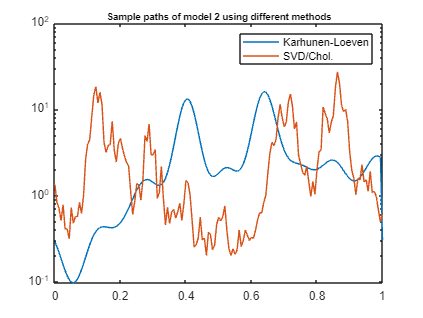

% Discretization of random field
N = 20;

% Discretization of FEM
l = 3;
I = N*2^l;

% Discretization of the FEM
x = linspace(0, 1, I+1);

% Parameters
sigma = 0.5; % Model 1
nu = 0.5; % Model 2


% Model 1
sample_model1 = a_constant_coeff(x, N, sigma);

% Model 2 using SVD/Cholesky
sample_decomp = a_matern(x, nu);

% Model 2 using KL expansion
sample_KL = a_KL_expansion(x, nu, N);

% Model 2 using Fourier expansion
% TODO

% Plot of samples
semilogy(x, sample_KL, x, sample_decomp)
legend('Karhunen-Loeven', 'SVD/Chol.')
title("Sample paths of model 2 using different methods", fontsize=8)

Now using these methods to sample the random field $a(x,w)$ we can approximate the PDE using FEM